# Quadruped robot multiobject optimization 

# Alternative Step 1 - Search trajectory of leg movments 

Here we are trying to teach a quadruped robot to walk using a genetic algorithm (GA).

A gait is defined as trajectory of waypoints for the reference hip and knee joint angles. These waypoints are evenly spaced in time over a predefined gait period and repeated for the duration of the simulation. Unlike quadruped_robot_optimization.m, this script uses multi-object optimization

## Run previous model

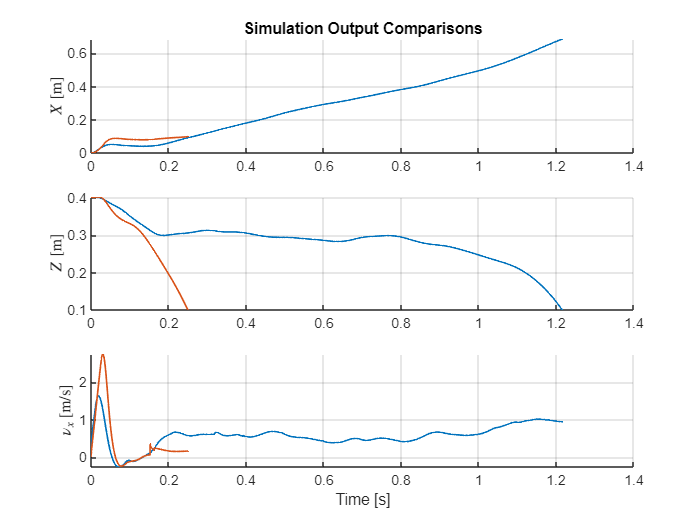

clc; clear;
typeBody = 1;
path_prev = ['ResultMultiOptimize/' 'bouncing_PD_ctrl_num_1_optimizedData_16Apr22_1120'];
run_previous;

[meanZ, meanVel, CoT] = PlotCoM_xyz(prev_simout,actuatorType);


disp(['Main characteristics. Mean Z position: ' num2str(meanZ) ...
       ' [m], mean velocity forward: ' num2str(meanVel)...
       ' [m/s], Cost Of Transport: ' num2str(CoT)])

Main characteristics. Mean Z position: 0.31262 [m], mean velocity forward: 0.34722 [m/s], Cost Of Transport: 0.6445


## Set parameters for optimization

Define the desired velocity, type of actuators and total gait time (each point is evenly spaced within this time)

clear prev_simout path_prev meanZ meanVel CoT;
clear;
% Choose type control of legs
% 1 - Motor; 2 - PD control
actuatorType = 2;

% Set desired velocity for optimization
v_des = 1.5; % [m/s]

% Set desired mean z position
z_des = 0.3; % [m]

 % Period of walking gait [s]
gait_period = 0.4;

## Set initial parameters

Open the optimization model and define paramaters

robotParameters;
typeBody = 1; % Body's type is without spine 
numPoints = 6; % Number of joint angle points
mdlName = 'QR_Unitree'; % Main model
open_system(mdlName);

To reduce the search space, scale the angle waypoints and solve the optimization algorithm with integer parameters. This scaling factor is from degrees to an integer.

scalingFactor = 2;

Create initial conditions to seed the initial population for optimization. Alternatively you can load from one of the presaved MAT-files provided in the `SavedResults` folder, as long as you use the scaling factor below to convert the gait waypoints.


% You can fill inital population previous data 

% p0 = [femur_motionFront(1:end-1),...
%     tibia_motionFront(1:end-1),...
%     femur_motionFront(1:end-1),...
%     tibia_motionFront(1:end-1),...
%     delta_gait_front, delta_gait_rear];

## Set optimization options

The options for the genetic algorithm are defined using the [`optimoptions`](https://www.mathworks.com/help/optim/ug/optim.problemdef.optimizationproblem.optimoptions.html) function.

% Compile the model to run a single simulation faster
accelFlag = true;
% Use parallel computing on multiple cores on your machine or on a cluster or cloud,
% if available
parallelFlag = true;  

population_size = 50;
opts = optimoptions('gamultiobj');
opts.Display = 'iter';
opts.MaxGenerations = 30;
opts.PopulationSize = population_size;
opts.UseVectorized = false;
% Add progress plot of fitness functionopt
opts.PlotFcn = {@gaplotrankhist, @gaplotpareto}; 
opts.UseParallel = parallelFlag;
% opts.InitialPopulationMatrix = repmat(p0,[population_size 1]);

% opts.MutationFcn = @mutationadaptfeasible;
% opts.HybridFcn = {@patternsearch,psOptions};

## Set joint angle bounds and constraints

upperBnd = [-70*ones(1,numPoints), ... % Femur Front Leg 
            90*ones(1,numPoints), ... % Tibia Front Leg 
            -70*ones(1,numPoints), ... % Femur Rear Leg 
            90*ones(1,numPoints), ... % Tibia Rear Leg 
            50*ones(1,2)] ... % Delay in percent
            /scalingFactor;
lowerBnd = [-180*ones(1,numPoints), ... % Femur Front Leg
            20*ones(1,numPoints), ... % Tibia Front Leg
            -180*ones(1,numPoints), ... % Femur Rear Leg 
            20*ones(1,numPoints), ... % Tibia Rear Leg 
            0.1*ones(1,2)] ... % Delay in percent
            /scalingFactor;
doSpeedupTasks;

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


## Run optimization

Here we use the [`ga`](https://www.mathworks.com/help/gads/ga.html)`multi` function from Global Optimization Toolbox to optimize the walking gait, with **simulateQuadrupedRobotMulti** as the fitness function.

costFcn = @(p)simulateQuadrupedRobotMulti(p,mdlName,scalingFactor,gait_period,v_des,actuatorType,z_des);
disp(['Running optimization. Population: ' num2str(opts.PopulationSize) ...
       ', Max Generations: ' num2str(opts.MaxGenerations)])

Running optimization. Population: 50, Max Generations: 30



Multi-objective optimization:
26 Variable(s)
26 Integer variable(s)

Options:
CreationFcn:       @gacreationsobol
CrossoverFcn:      @crossoverintermediate
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower
 --------------------------------------------------------------------------------
          Zero-crossing signal index : 32
           Zero-crossing signal name : AbsZc
                          Block type : Abs
                          Block path : 'QR_Unitree/Leg_Right_Rear/Subsystem1/PD control/Abs'
--------------------------------------------------------------------------------
 The search algorithm only detected these zero crossings because of the presence of other zero crossings in this time step. Masked zero crossings are ca

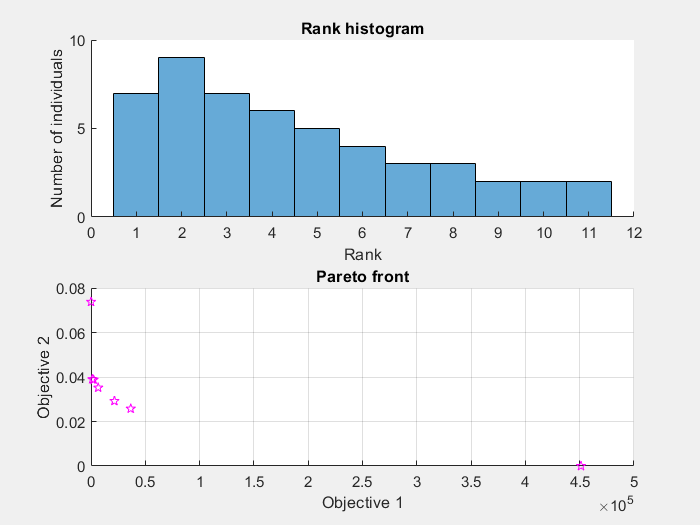

[pFinal,reward] = gamultiobj(costFcn,numPoints*4+2,[],[],[],[], ... 
                      lowerBnd,upperBnd,[],1:numPoints*4+2,opts);

disp(['Final reward function value: ' num2str(reward(end))])

Final reward function value: 0.035199


## Analyze and save results

Convert from optimization integer search space to trajectories in radians

for idx = 1:size(pFinal,1)
pScaled = scalingFactor*pFinal(idx,:);
reward_iter = reward(idx,:);
traj_times = linspace(0,gait_period,numPoints+1);
femur_motionFront = deg2rad([pScaled(1:numPoints) pScaled(1)]);
tibia_motionFront = deg2rad([pScaled(numPoints+1:2*numPoints) pScaled(numPoints+1)]);
femur_motionRear = deg2rad([pScaled(2*numPoints+1:3*numPoints) pScaled(2*numPoints+1)]);
tibia_motionRear = deg2rad([pScaled(3*numPoints+1:4*numPoints) pScaled(3*numPoints+1)]);
delta_gait_front = pScaled(end-1);
delta_gait_rear = pScaled(end);

Evaluate the trajectory at a few points for visualization

numTrajPoints = 101;
evalTimes = linspace(0,gait_period,numTrajPoints);
[q_fr,fem_der_front,tib_der_front] = createSmoothTrajectory(femur_motionFront,tibia_motionFront,gait_period,evalTimes);
[q_rr,fem_der_rear,tib_der_rear] = createSmoothTrajectory(femur_motionRear,tibia_motionRear,gait_period,evalTimes);

Plot the resulting trajectory

% figure
% subplot(2,1,1)
% plot(evalTimes,rad2deg(q_fr(1,:)),'b-',traj_times,rad2deg(femur_motionFront),'ro');
% title('Final Optimized Gait for Front Legs')
% xlabel('Time [s]');
% ylabel('Hip Angles [deg]');
% subplot(2,1,2)
% plot(evalTimes,rad2deg(q_fr(2,:)),'b-',traj_times,rad2deg(tibia_motionFront),'ro');
% xlabel('Time [s]');
% ylabel('Knee Angles [deg]');
% figure
% subplot(2,1,1)
% plot(evalTimes,rad2deg(q_rr(1,:)),'b-',traj_times,rad2deg(femur_motionRear),'ro');
% title('Final Optimized Gait for Rear Legs')
% xlabel('Time [s]');
% ylabel('Hip Angles [deg]');
% subplot(2,1,2)
% plot(evalTimes,rad2deg(q_rr(2,:)),'b-',traj_times,rad2deg(tibia_motionRear),'ro');
% xlabel('Time [s]');
% ylabel('Knee Angles [deg]');

Save results to a timestamped MAT-file

choice_ctrl_legs;
if v_des < 0.9
    type_locomotion = 'walk';
elseif v_des >= 0.9 && v_des < 1.5
    type_locomotion = 'trot';
elseif v_des >= 1.5 
    type_locomotion = 'bouncing';
end
save_actType = actuatorType;
save_bodyType = typeBody;
strFile = '';
outFileName = ['ResultMultiOptimize/' type_locomotion '_'  ctrl_name '_num_' idx '_optimizedData_' datestr(now,'ddmmmyy_HHMM')];
for idx1 = 1:numel(outFileName)
    strFile = strcat(strFile,outFileName(idx1));
end
disp(strFile);
save(strFile,...
    'reward_iter','gait_period','traj_times','femur_motionFront','tibia_motionFront','delta_gait_front',...
    'femur_motionRear','tibia_motionRear','delta_gait_rear',...
    'save_actType','save_bodyType');
end

ResultMultiOptimize/bouncing_PD_ctrl_num_1_optimizedData_16Apr22_1120
ResultMultiOptimize/bouncing_PD_ctrl_num_2_optimizedData_16Apr22_1120
ResultMultiOptimize/bouncing_PD_ctrl_num_3_optimizedData_16Apr22_1120
ResultMultiOptimize/bouncing_PD_ctrl_num_4_optimizedData_16Apr22_1120
ResultMultiOptimize/bouncing_PD_ctrl_num_5_optimizedData_16Apr22_1120
ResultMultiOptimize/bouncing_PD_ctrl_num_6_optimizedData_16Apr22_1120
ResultMultiOptimize/bouncing_PD_ctrl_num_7_optimizedData_16Apr22_1120


delete(gcp('nocreate'));

## Simulate optimize model and plot figures

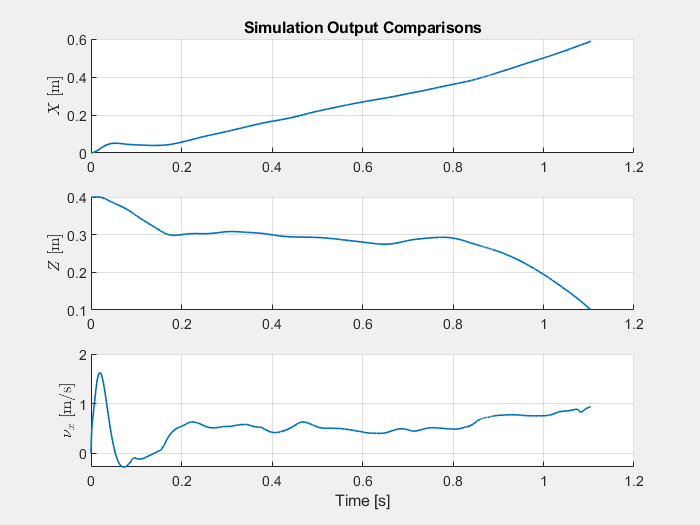

typeBody = 1;
path_prev = strFile;
run_previous;

[meanZ, meanVel, CoT] = PlotCoM_xyz(prev_simout,actuatorType);


disp(['Main characteristics. Mean Z position: ' num2str(meanZ) ...
       ' [m], mean velocity forward: ' num2str(meanVel)...
       ' [m/s], Cost Of Transport: ' num2str(CoT)])

Main characteristics. Mean Z position: 0.28231 [m], mean velocity forward: 0.55789 [m/s], Cost Of Transport: 0.32626
